# 1.1 FFT and FFT Shift 1D

clear all; close all;
%1.1.1-1.1.5
f1=10;
A=7;

fs=200;
Ts=1/fs;
t=0:Ts:1-Ts;
y1=A*sin(2*pi*t*f1);


F=fft(y1);
Fshift=fftshift(F);
Fangle=angle(F);

1.1.1-3 f= 10hz

        figure;
        subplot(2,3,1); plot(t,y1); title('7sin(2\pit\bullet10)');
        subplot(2,3,2); plot(abs(F)); title('abs(fft(y))');
        subplot(2,3,3); plot(abs(Fshift)); title('abs(fftshift(F))');
        subplot(2,3,4); plot(log(abs(F))); title('log(abs(F))');
        subplot(2,3,5); plot(log(abs(Fshift))); title('log(abs(fft(y)))');
        subplot(2,3,6); plot(fftshift(Fangle)); title('angle(F)');

1.1.4  f=10.541

        f2=10.541;
        y2=A*sin(2*pi*t*f2);
        F2=fft(y2);
        Fshift2=fftshift(F2);
        Fangle2=angle(F2);
    
        figure;
        subplot(2,3,1); plot(t,y2); title('7sin(2\pit\bullet10.541)');
        subplot(2,3,2); plot(t,abs(F2)); title('abs(fft(y2))');
        subplot(2,3,3); plot(t,abs(Fshift2)); title('abs(fftshift(F2))');
        subplot(2,3,4); plot(t,log(abs(F2))); title('log(abs(F2))');
        subplot(2,3,5); plot(t,log(abs(Fshift2))); title('log(abs(fft(y2)))');
        subplot(2,3,6); plot(t,fftshift(Fangle2)); title('angle(F2)');

1.1.1.5 ad DC to the signal: 

    
    y3=127*(sin(2*pi*t*f1)+1);
    F3=fft(y3);
    Fshift3=fftshift(F3);
    Fangle3=angle(F3);

        figure;
        subplot(2,3,1); plot(t,y3); title('127(sin(2\pit\bullet10)+1)');
        subplot(2,3,2); plot(t,abs(F3)); title('abs(fft(y))');
        subplot(2,3,3); plot(t,abs(Fshift3)); title('abs(fftshift(F))');
        subplot(2,3,4); plot(t,log(abs(F))); title('log(abs(F))');
        subplot(2,3,5); plot(t,log(abs(Fshift3))); title('log(abs(fft(y)))');
        subplot(2,3,6); plot(t,Fangle3); title('angle(F)');        

 1.1.1.6 real signal property

The magnitude of the real signal is even function and the phase is odd function.         

## 1.2 ifft

1.2.1

    f1=10; f2=10.541;
    A=7;

    fs=200;
    Ts=1/fs;
    t=0:Ts:1;

    y1=A*sin(2*pi*t*f1); y2=A*sin(2*pi*t*f2); y3=127*(sin(2*pi*t*f1)+1);

    F=fft(y1); F2=fft(y2);F3=fft(y3); 
    Fshift=fftshift(F); Fshift2=fftshift(F2); Fshift3=fftshift(F3);


    iF1=ifft(F); iF2=ifft(F2);iF3=ifft(F3);
    deltaF1=y1-iF1; deltaF2= y2-iF2; deltaF3=y3-iF3;
     Snr1=snr(y1,deltaF1);
     Snr2=snr(y2,deltaF2);
     Snr3=snr(y3,deltaF3);
     MSE1=immse(y1,iF1);
     m1=sqrt(MSE1);
     MSE2=immse(y2,iF2);
     m2=sqrt(MSE2);
     MSE3=immse(y3,iF3);
     m3=sqrt(MSE3);
     Psnr1=psnr(y1,deltaF1);
     Psnr2=psnr(y2,deltaF2);
     Psnr3=psnr(y3,deltaF3);
    
    figure;
    subplot(2,3,1); plot(t,y1); title('7sin(2\pit\bullet10.541)');
    subplot(2,3,2); plot(t,y2); title('7sin(2\pit\bullet10)');
    subplot(2,3,3); plot(t,y3); title('127(sin(2\pit\bullet10)+1)');
    subplot(2,3,4); plot(t,iF1); title('ifft(F1)');
    subplot(2,3,5); plot(t,iF2); title('ifft(F2)');
    subplot(2,3,6); plot(t,iF3); title('ifft(F3)');
    

1.2.2

    
    figure; plot(t,deltaF1); title(['y1-ifft(F1) SNR: ' num2str(Snr1) ' PSNR: ' num2str(Psnr1) ' sqr(MSE): ' MSE1]);
    figure; plot(t,deltaF2); title(['y2-ifft(F2) SNR: ' num2str(Snr2) ' PSNR: ' num2str(Psnr2) ' sqr(MSE): ' MSE2]);
    figure; plot(t,deltaF3); title(['y3-ifft(F3) SNR: ' num2str(Snr3) ' PSNR: ' num2str(Snr3) ' sqr(MSE): ' num2str(Snr3) ]);

## 1.3

 1.3.1-4       

f = [1 2 3 1 2 0];
h = [1 1 0 0 0 0];
g=conv(f,h);
%1.3.2
F=fft(f);
H=fft(h);
G=H.*F; Gt=ifft(G);
figure;
subplot(2,3,1); stem(f); title('f');
subplot(2,3,2); stem(h); title('h');
subplot(2,3,3); stem(g); title('g'); xlim([0 10]);
subplot(2,3,4); stem(abs(F)); title('abs(fft(f))');
subplot(2,3,5); stem(abs(H)); title('abs(fft(H))');
subplot(2,3,6); stem(Gt); title('F^-^1[G]'); xlim([0 10]);

## 1.4

fs= 210;f1=10;f2=30;f3=70;
time=1; dt=1/fs; t=0:dt:(time-dt);
f=1./t;
t1= -105:1:104;

sinus= sin(f1*2*pi*t)+ sin(f2*2*pi*t) + sin(f3*2*pi*t);
fftsinus = fft(sinus);
lpf=[ones(1,15) zeros(1,181) ones(1,14)];
hpf=[zeros(1,65) ones(1,81) zeros(1,64)];
bpf=[zeros(1,15) ones(1,20) zeros(1,141) ones(1,20) zeros(1,14)]; 
sinuslpf=fftsinus.*lpf;
sinushpf=fftsinus.*hpf;
sinusbpf=fftsinus.*bpf;
subplot(2,1,1);plot(sinus);title('sin(10*2*pi*t)+ sin(30*2*pi*t) + sin(70*2*pi*t)');
subplot(2,1,2);plot(t1,fftshift(abs(fftsinus)));title('fft of sinus');
figure;
subplot(3,3,1);plot(t1,fftshift(abs(sinuslpf)));title('fft sinuslpf');
subplot(3,3,2);plot(t1,fftshift(abs(sinushpf)));title('fft sinushpf');
subplot(3,3,3);plot(t1,fftshift(abs(sinusbpf)));title('fft sinusbpf');
subplot(3,3,4);plot(t1,fftshift(lpf));title('lpf');
subplot(3,3,5);plot(t1,fftshift(hpf));title('hpf');
subplot(3,3,6);plot(t1,fftshift(bpf));title('bpf');
subplot(3,3,7);plot(ifft(abs(sinuslpf)));title('sin(10*2*pi*t)');
subplot(3,3,8);plot(ifft(abs(sinushpf)));title('sin(70*2*pi*t)');
subplot(3,3,9);plot(ifft(abs(sinusbpf)));title('sin(30*2*pi*t)');

## 2 

2.1 

ft :

ift:

 fourier invert return the original function in time

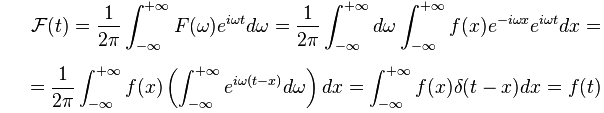

**fftshift vs ifftshift:**

fftshift - Shift zero-frequency component to center of spectrum

ifftshift - rearranges a zero-frequency-shifted Fourier transform `Y` back to the original transform output. In other words, `ifftshift` undoes the result of `fftshift`.

2.1.1.1-4 we at the warm exercies.

## 2.1.1.5

img=imread('tire.tif');
x=img(120,:);
[m,n]=size(x);
t = linspace(0,n,n);
F=fft(x);
Fshift=fftshift(F);
Fangle=angle(F);


 figure;
        subplot(2,3,1); plot(t,x); title('the 1st line)');
        subplot(2,3,2); plot(abs(F)); title('abs(fft(y))');
        subplot(2,3,3); plot(abs(Fshift)); title('abs(fftshift(F))');
        subplot(2,3,4); plot(log(abs(F))); title('log(abs(F))');
        subplot(2,3,5); plot(log(abs(Fshift))); title('log(abs(fft(y)))');
        subplot(2,3,6); plot(fftshift(Fangle)); title('angle(F)');

## 2.2.1

Demonstration:


img=imread('cameraman.tif');
F=fft2(img);
Fangle=angle(F);
figure;       
subplot(2,2,1); imshow(img); title('original');
subplot(2,2,2); imshow(log(abs(F)),[]); title('log(abs(F))');
subplot(2,2,3); imshow(fftshift(Fangle),[]); title('angle(F) with fftshift');
subplot(2,2,4); imshow(fftshift(log(abs(F))),[]); title('log(abs(fftshift(F))');

img=imread('imageToAnalyze.png');

i=abs(fft2(img));
ff=(abs(fft2(i))+1);
ffs=fftshift(ff); 
phase1=angle(fftshift(fft2(i)));


imshow(fftshift(i),[]);title('fft of signal 1');
figure;
imshow(ffs,[]);title('magnitude of signal 1');
figure;
imshow(phase1,[]);title('phase of signal 1');
figure;
mesh(fftshift(i)); title('signal1 Magnitude');

## 2.2.1.1-5 

clear all; close all;
h = 64; w = 128;
f1 = 2;
f2 = 8; 
x = 0:(w-1); 
y = 0:(h-1);
[X,Y] = meshgrid(x,y);
% Generate signals and FFT2 them
s1 = cos(2*pi*X/w*f1).*cos(2*pi*Y/w*f1);
s1_fft = fft2(s1);
s2 = cos(2*pi*X/w*f2).*cos(2*pi*Y/w*f2);
s2_fft = fft2(s2);

a) plot signals and  FFT

figure(1);
subplot(2,2,1);
imshow(s1,[]); title('Signal 1');
subplot(2,2,3);
imshow(s2,[]); title('Signal 2');
subplot(2,2,2);
imshow((log(abs(s1_fft))),[]); title('abs of FFT of signal 1');
subplot(2,2,4);
imshow((log(abs(s2_fft))),[]); title('abs of FFT of signal 2');

 b) check influence of FFTshift

figure(2);
subplot(2,2,1);
imshow(s1,[]); title('Signal 1');
subplot(2,2,3);
imshow(s2,[]); title('Signal 2');
subplot(2,2,2);
imshow((log(abs(fftshift(s1_fft)))),[]); title('abs of FFTshift of signal 1');
subplot(2,2,4);
imshow((log(abs(fftshift(s2_fft)))),[]); title('abs of FFTshift of signal 2');

c) Magnitude & Phase

figure(3);
subplot(2,2,1);
imshow(log((abs(s2_fft))),[]);
title('Signal 2 Magnitude');
subplot(2,2,3);
imshow(log(fftshift(abs(s2_fft))),[]);
title('Signal 2 fftshift Magnitude');
subplot(2,2,2);
imshow(angle(s2_fft),[]);
title('Signal 2 Phase');
subplot(2,2,4);
imshow(fftshift(angle(s2_fft)),[]);
title('Signal 2 fftshift Phase');

d) 3D plot with mesh grid

figure(4);
subplot(1,2,1);
mesh(X,Y,log(abs(s1_fft)));
title('Signal 1 Magnitude');
subplot(1,2,2);
mesh(X,Y,log(fftshift(abs(s1_fft))));
title('Signal 1 fftshift Magnitude');

d) Add gauss noise

s3 = imnoise(s2,'gaussian',0,0.01);
s3_fft = fft2(s3);
% Repeat for noise added signal
figure(5);
imshow(s3,[]); title('S_3 = S_2+noise');
figure(6);
subplot(2,2,1);
imshow(log(abs(s3_fft)),[]); title('s_3 magnitude');
subplot(2,2,2);
imshow(log(fftshift(abs(s3_fft))),[]); title('s3+fftshift Magnitude');
subplot(2,2,3);
imshow(angle(s3_fft),[]); title('s_3 Phase');
subplot(2,2,4);
imshow(fftshift(angle(s3_fft)),[]);
title('s_3+fftshift Phase');
% 3D plot with mesh grid
figure(7);
subplot(1,2,1);
mesh(X,Y,log(abs(s3_fft))); title('s_3 magnitude');
subplot(1,2,2);
mesh(X,Y,log(fftshift(abs(s3_fft))));
title('s3+fftshift Magnitude');

using log on fft allow as to see freqncey with lower magnitude with ease.  

## 2.3.1

clear all; close all;
img=imread('cameraman.tif');
F=fft2(img);
Fangle=angle(F);
mag=abs(F);
imgMag=ifft2(mag);
imgAngle=ifft2(exp(1i*Fangle));

figure;
subplot(2,3,1); imshow(img); title('original');
subplot(2,3,2); imshow(log(abs(F)),[]); title('log(abs(F))');
subplot(2,3,3); imshow(fftshift(Fangle),[]); title('angle(F) with fftshift');
subplot(2,3,4); imshow(fftshift(log(abs(F))),[]); title('abs(fftshift(F))');
subplot(2,3,5); imshow(imgMag,[]); title('magnitude based');
subplot(2,3,6); imshow(imgAngle,[]); title('phase based');

## 2.3.1.2

clear all; close all;
img1=imread('cameraman.tif');
img2=imread('text.png');
F1=fft2(img1);F2=fft2(img2);
F1angle=angle(F1);F2angle=angle(F2);
mag1=abs(F1);mag2=abs(F2);
angle1=exp(1i*F1angle);angle2=exp(1i*F2angle);
new1=angle1.*mag2;
new2=angle2.*mag1;
newimg1=real(ifft2(new1));
newimg2=real(ifft2(new2));
figure;    
subplot(2,2,3); imshow(newimg1,[]); title('phase cameraman magnitude text');
subplot(2,2,1); imshow(img1); title('original 1');
subplot(2,2,4); imshow(newimg2,[]); title('magnitude cameraman phase text');
subplot(2,2,2); imshow(img2); title('original 2');

## 2.3.2

Our eye is more sensitive to phase than size so we cannot see much detail about size despite the phase.

We can make such an upgrade by adjusting the magnitude to the changes in the image phase (between pixel and pixel) - we will change the magnitude in direct proportion to the phase changes.

  close all; clear all; 
  img = imread('text.png');
  imfft=fft2(img);
  imffts=fftshift(imfft);          
  imangle=angle(imfft);  
  imReMag=real(ifft2(abs(imfft)));        
  imRePhase=real(ifft2(1*exp(1i*imangle))); 
  
  figure; 
  subplot(2,3,1); imshow(img) ; title('original');
  subplot(2,3,2); imshow(log(abs(imfft)),[]); title('magnitude, no fftshift');
  subplot(2,3,3); imshow(log(abs(imffts)),[]); title('magnitude, with fftshift');
  subplot(2,3,4); imshow(imangle,[]); title('phase');
  subplot(2,3,5); imshow(real(imReMag),[]); title('magnitude based');
  subplot(2,3,6); imshow(real(imRePhase),[]); title('phase based');

## 2.4.1

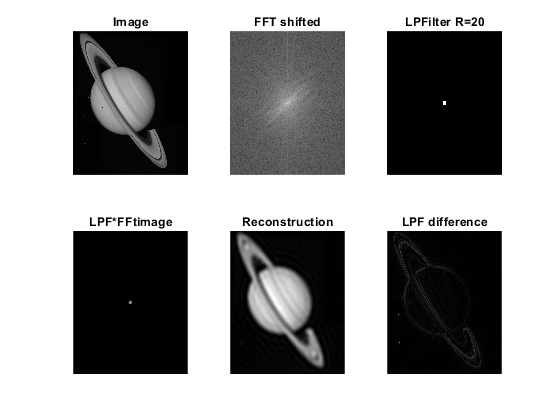

close all; clear all;
img=double(rgb2gray(imread('saturn.png')));

[m,n]=size(img);

[x1,y1] = meshgrid(1:n,1:m);
cx=(n)/2; cy=(m)/2;
X=(x1 - cx); Y=(y1 - cy);
R=X.^2 + Y.^2;
r1=20; r2=30;
LPF =  R <= r1^2;
HPF =  R >= r1^2;
BPF = (R >= r1^2) & (R <= r2^2);
BSF = (R <= r1^2) | (R >= r2^2);
imgfft=fft2(img);
imgfftshift=fftshift(imgfft);
imglpf=imgfftshift.*double(LPF);
imghpf=imgfftshift.*double(HPF);
imgbpf=imgfftshift.*double(BPF);
imgbsf=imgfftshift.*double(BSF);
lpfimg=ifft2(ifftshift(imglpf));
hpfimg=ifft2(ifftshift(imghpf));
bpfimg=ifft2(ifftshift(imgbpf));
bsfimg=ifft2(ifftshift(imgbsf));
deltalpf=img-double(real(lpfimg));
deltahpf=img-double(real(hpfimg));
deltabpf=img-double(real(bpfimg));
deltabsf=img-double(real(bsfimg));

figure(); %lpf
subplot(2,3,1); imshow(uint8(img)); title('Image');
subplot(2,3,2); imshow(log(abs(imgfftshift)),[]); title('FFT shifted');
subplot(2,3,3); imshow(LPF); title(['LPFilter R=',num2str(r1)]);
subplot(2,3,4); imshow(log(abs(imglpf)),[]); title('LPF*FFtimage');
subplot(2,3,5); imshow(abs(lpfimg),[]); title('Reconstruction');
subplot(2,3,6); imshow(uint8(abs(deltalpf))); title('LPF difference');

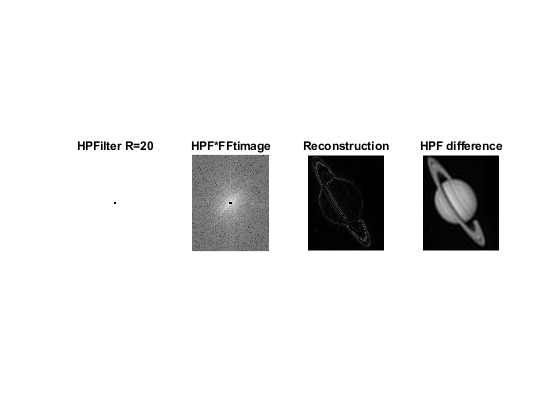


figure(); %hpf
subplot(1,4,1); imshow(HPF); title(['HPFilter R=',num2str(r1)]);
subplot(1,4,2); imshow(log(abs(imghpf)),[]); title('HPF*FFtimage');
subplot(1,4,3); imshow(abs(hpfimg),[]); title('Reconstruction');
subplot(1,4,4); imshow(uint8(abs(deltahpf))); title('HPF difference');

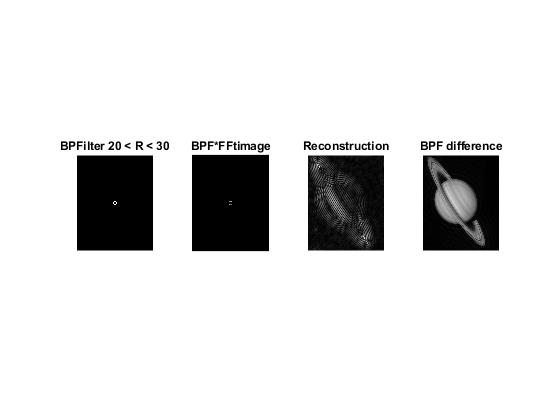


figure(); %bpf
subplot(1,4,1); imshow(BPF); title(['BPFilter ',num2str(r1),' < R < ',num2str(r2)]);
subplot(1,4,2); imshow(log(abs(imgbpf)),[]); title('BPF*FFtimage');
subplot(1,4,3); imshow(abs(bpfimg),[]); title('Reconstruction');
subplot(1,4,4); imshow(uint8(abs(deltabpf))); title('BPF difference');

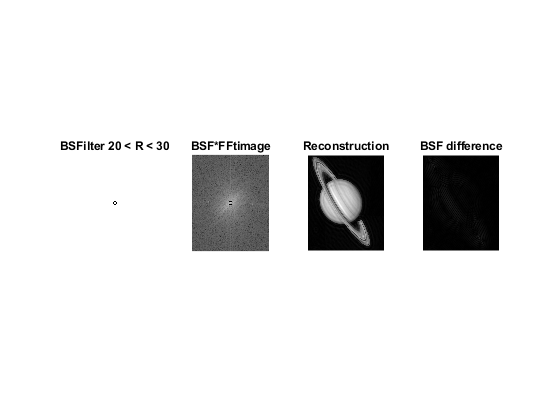


figure(); %bsf
subplot(1,4,1); imshow(BSF); title(['BSFilter ',num2str(r1),' < R < ',num2str(r2)]);
subplot(1,4,2); imshow(log(abs(imgbsf)),[]); title('BSF*FFtimage');
subplot(1,4,3); imshow(abs(bsfimg),[]); title('Reconstruction');
subplot(1,4,4); imshow(uint8(abs(deltabsf))); title('BSF difference');